% ESA Dynamics HW4 - Double Pendulum
% Chris Allum 4.22.21
clc
clearvars

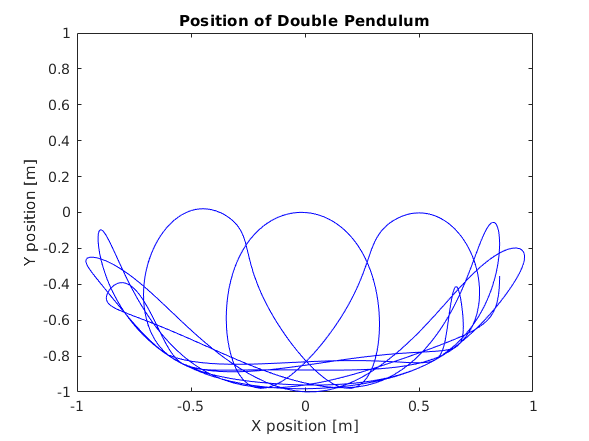

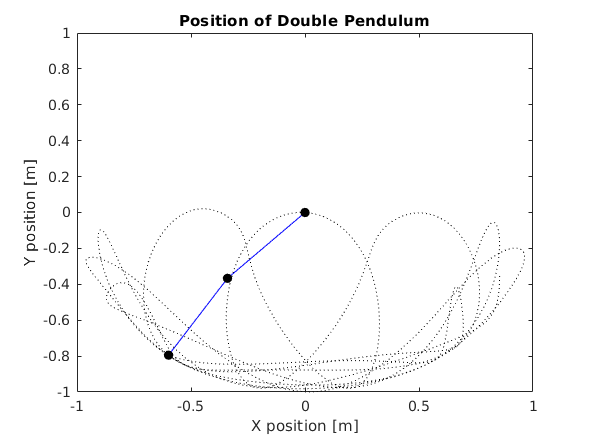

% system params
l1 = .5;
l2 = .5;
m1 = 1;
m2 = 1;
g = 9.8;

% initial position
theta10 = pi/2;
theta20 = pi/4;

% initial velocity
dtheta10 = 0;
dtheta20 = 0;

% pack initial conditions and params into vectors
params = [l1 l2 m1 m2 g]';
init = [theta10 dtheta10 theta20 dtheta20]';

% run simulation
[t,p] = DoublePendulum(params,init);

% plot path
PlotPendulum(p,params)

% show animation of pendulum
AnimatePendulum(p,params)

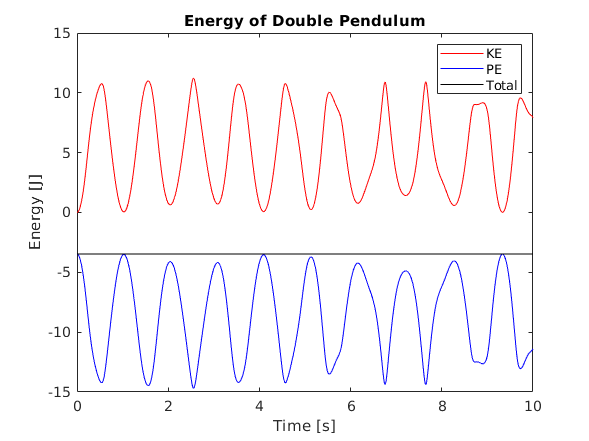


% energy calcs
EnergyCalculations(t,p,params)

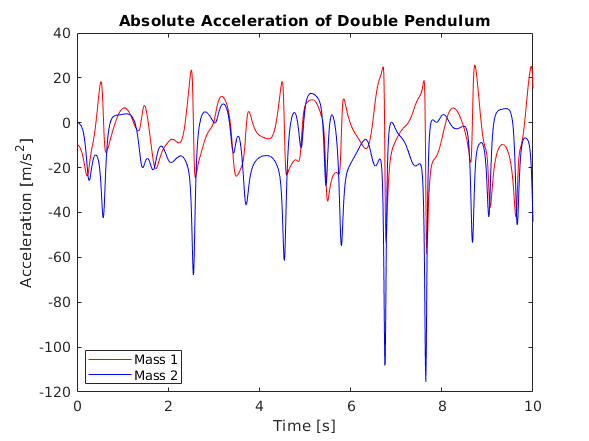

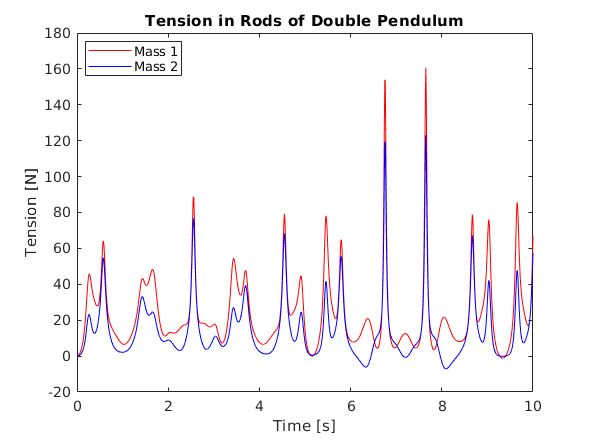


% acceleration calcs
AccelerationCalculations(t,p,params)

function [t,p] = DoublePendulum(params,init)
    
    % time span
    tspan = [0:.01:10];
    
    % simulation params, used in ODE funcs
    l1 = params(1);     % m
    l2 = params(2);     % m
    m1 = params(3);     % kg
    m2 = params(4);     % kg
    g = params(5);      % m/s^2
    
    % use ode45 and stop at event
    options = odeset("RelTol",1.0e-6);
    [t,p] = ode45(@f,tspan,init,options);
    
    % define ODEs
    function dpdt = f(~,p)
        q = [1 0 0 0 0 0;
             0 m1*l1 0 0 0 -sin(p(3)-p(1));
             0 0 1 0 0 0;
             l1*p(2)*sin(p(3)-p(1)) l1*cos(p(3)-p(1)) 0 l2 0 0;
             -m1*l1*p(2) 0 0 0 1 -cos(p(3)-p(1));
             -l1*p(2)*cos(p(3)-p(1)) l1*sin(p(3)-p(1)) -l2*p(4) 0 0 1/m2];
        
        r = [p(2);
            -m1*g*sin(p(1));
            p(4);
            -g*sin(p(3));
            m1*g*cos(p(1));
            g*cos(p(3))];
        
        z = (q\r)';
        
        dtheta1= z(1);
        ddtheta1 = z(2);
        dtheta2 = z(3);
        ddtheta2 = z(4);

        % pack ODEs into column vector
        dpdt = [dtheta1 ddtheta1 dtheta2 ddtheta2]';
    end

end

function PlotPendulum(p,params)
    % create r1, r2, r3 vectors
    theta1 = p(:,1);
    theta2 = p(:,3);
    l1 = params(1);     % m
    l2 = params(2);     % m
    
    pendulum1 = [l1*sin(theta1) -l1*cos(theta1)];   % m1 pendulum
    pendulum2 = [l2*sin(theta2) -l2*cos(theta2)];   % m2 pendulum
    pendulum_tot = pendulum1 + pendulum2;
    
    figure
    plot(pendulum_tot(:,1),pendulum_tot(:,2),"-b")
    axis([-(l1+l2) l1+l2 -(l1+l2) l1+l2])
    title("Position of Double Pendulum")
    xlabel("X position [m]")
    ylabel("Y position [m]")
    
end

function AnimatePendulum(p,params)
    % create r1, r2, r3 vectors
    theta1 = p(:,1);
    theta2 = p(:,3);
    l1 = params(1);     % m
    l2 = params(2);     % m
    
    pendulum1 = [l1*sin(theta1) -l1*cos(theta1)];   % m1 pendulum
    pendulum2 = [l2*sin(theta2) -l2*cos(theta2)];   % m2 pendulum
    pendulum_tot = pendulum1 + pendulum2;
    
    h = figure();
    %set(gcf,'Visible','on')
    for point = 1:length(pendulum_tot)
        
        % create pendulum arms vectors
        pendulum_arms_x = [0 pendulum1(point,1);
                           pendulum1(point,1) pendulum_tot(point,1)];
        pendulum_arms_y = [0 pendulum1(point,2);
                           pendulum1(point,2) pendulum_tot(point,2) ];
        
        % plot pendulum arms
        plot(pendulum_arms_x,pendulum_arms_y,"-b","MarkerSize",5), hold on
        
        % create pendulum mass points
        x = [pendulum1(point,1) pendulum_tot(point,1)];
        y = [pendulum1(point,2) pendulum_tot(point,2)];

        % plot pendulum mass points
        plot(x,y,"ok",'MarkerFaceColor','k')
        
        % plot pendulum origin
        plot(0,0,"ok",'MarkerFaceColor','k')
        
        % create trail points
        trail_x = pendulum_tot(1:point,1);
        trail_y = pendulum_tot(1:point,2);
        
        % plot trail
        plot(trail_x,trail_y,":k","MarkerSize",.1),hold off
        
        axis([-(l1+l2) l1+l2 -(l1+l2) l1+l2])
        xlabel("X position [m]")
        ylabel("Y position [m]")
        title("Position of Double Pendulum")
        drawnow
        
    end
end

function EnergyCalculations(t,p,params)
    % create r1, r2, r3 vectors
    theta1 = p(:,1);
    theta1_d = p(:,2);
    theta2 = p(:,3);
    theta2_d = p(:,4);
    l1 = params(1);     % m
    l2 = params(2);     % m
    m1 = params(3);
    m2 = params(4);
    g = params(5);
    
    x1_v = theta1_d.*l1.*cos(theta1);
    x2_v = x1_v + theta2_d.*l2.*cos(theta2);
    y1_v = l1.*theta1_d.*sin(theta1);
    y2_v = y1_v + theta2_d.*l2.*sin(theta2);
    
    pend1_V = sqrt(x1_v.^2 +y1_v.^2);
    pend2_v = sqrt(x2_v.^2 +y2_v.^2);
    
    KE_pend1 = .5*m1*pend1_V.^2;
    KE_pend2 = .5*m2*pend2_v.^2;
    Total_KE = KE_pend2+KE_pend1;
    
    Hm1 = (-l1.*cos(theta1));
    Hm2 = Hm1 + (- l2.*cos(theta2));
    
    PE_pend1 = m1*g.*(Hm1);
    PE_pend2 = m2*g.*(Hm2);
    PE_total = PE_pend2+PE_pend1;
    
    ETotal = PE_total+Total_KE;
    
    figure
    plot(t,Total_KE,"-r"), hold on
    plot(t,PE_total,"-b")
    plot(t,ETotal,"-k")
    xlabel('Time [s]')
    ylabel('Energy [J]')
    title('Energy of Double Pendulum')
    legend('KE',"PE",'Total', 'Location',"northeast")

end

function AccelerationCalculations(t,p,params)
    l1 = params(1);     % m
    l2 = params(2);     % m
    m1 = params(3);
    m2 = params(4);
    g = params(5);
    
    syms theta1 theta2 dtheta1 dtheta2 ddtheta1 ddtheta2 T1 T2
    
    q = [1 0 0 0 0 0;
         0 m1*l1 0 0 0 -sin(theta2-theta1);
         0 0 1 0 0 0;
         l1*dtheta1*sin(theta2-theta1) l1*cos(theta2-theta1) 0 l2 0 0;
         -m1*l1*dtheta1 0 0 0 1 -cos(theta2-theta1);
         -l1*dtheta1*cos(theta2-theta1) l1*sin(theta2-theta1) -l2*dtheta2 0 0 1/m2];
        
        r = [dtheta1;
            -m1*g*sin(theta1);
            dtheta2;
            -g*sin(theta2);
            m1*g*cos(theta1);
            g*cos(theta2)];
        
        z = (q\r)';
    
    dtheta1= z(1);
    ddtheta1 = z(2);
    dtheta2 = z(3);
    ddtheta2 = z(4);
    T1 = z(5);
    T2 = z(6);

    m1_accel = matlabFunction(-T1/m1 +g*cos(theta1) - g*sin(theta1) + T2*cos(theta2-theta1)/m1 + T2*sin(theta2-theta1)/m1);
    m2_accel = matlabFunction(-T2/m2 + g*cos(theta2) - g*sin(theta2));
    
    acceleration1 = m1_accel(p(:,2),p(:,4),p(:,1),p(:,3));
    acceleration2 = m2_accel(p(:,2),p(:,4),p(:,1),p(:,3));
    
    T1 = matlabFunction(T1);
    T2 = matlabFunction(T2);
    
    tension1 = T1(p(:,2),p(:,4),p(:,1),p(:,3));
    tension2 = T2(p(:,2),p(:,4),p(:,1),p(:,3));
    
    figure
    plot(t,acceleration1,"-r"), hold on
    plot(t,acceleration2,"-b")
    title("Absolute Acceleration of Double Pendulum")
    xlabel("Time [s]")
    ylabel("Acceleration [m/s^2]")
    legend(["Mass 1","Mass 2"],"Location","best")
    
    figure
    plot(t,tension1,"-r"),hold on
    plot(t,tension2,"-b")
    title("Tension in Rods of Double Pendulum")
    xlabel("Time [s]")
    ylabel("Tension [N]")
    legend(["Mass 1","Mass 2"],"Location","best")
end